min = -pi/2;
max = pi/2;
step = pi/8;
%Parameters
theta1 = 0.39269908169872414

theta1 = 0.3927

theta2 = 0.39269908169872414

theta2 = 0.3927

theta3 = -0.7853981633974483

theta3 = -0.7854


theta4 = -0.39269908169872414

theta4 = -0.3927

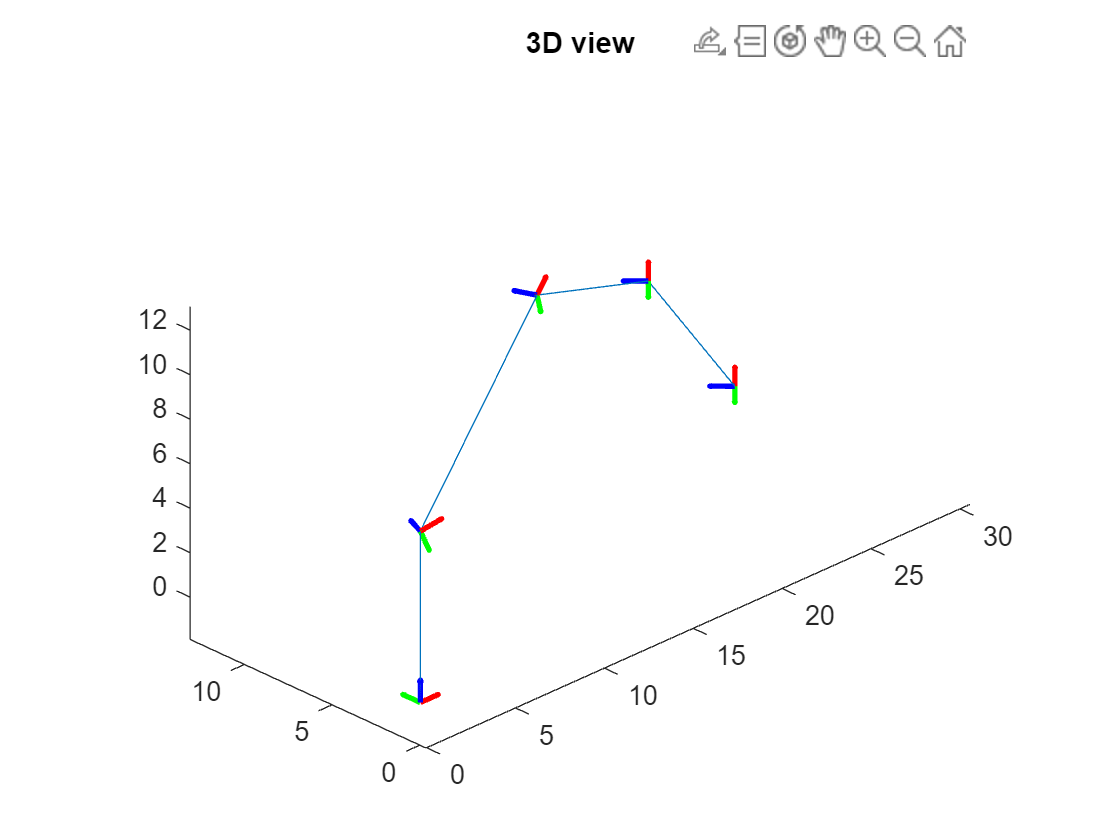

%%
% DH Table
DH = [
    0, 0, 7.7, theta1;
    0, pi/2, 0, theta2;%last should maybe be theta2?
    13, 0, 0, theta3;
    12.4, 0, 0, theta4;
    12.6, 0, 0, 0;
];
%%

%Transformations
T_0_0 = eye(4);
% T_0_1 = T_0_0 * dh_transform(DH(2,1),DH(2,2),DH(1,3),DH(1,4));
% T_1_2 = T_0_1 * dh_transform(DH(3,1),DH(3,2),DH(2,3),DH(2,4));
% T_2_3 = T_1_2 * dh_transform(DH(4,1),DH(4,2),DH(3,3),DH(3,4));
% T_3_4 = T_2_3 * dh_transform(DH(5,1),DH(5, 2),DH(4, 3),DH(4,4));
% T_4_5 = T_3_4 * dh_transform(0,0,DH(5, 3),DH(5,4));

T_0_1 = T_0_0 * dh_transform_new(DH(1,1),DH(1,2),DH(1,3),DH(1,4));
T_1_2 = T_0_1 * dh_transform_new(DH(2,1),DH(2,2),DH(2,3),DH(2,4));
T_2_3 = T_1_2 * dh_transform_new(DH(3,1),DH(3,2),DH(3,3),DH(3,4));
T_3_4 = T_2_3 * dh_transform_new(DH(4,1),DH(4, 2),DH(4, 3),DH(4,4));
T_4_5 = T_3_4 * dh_transform_new(DH(5,1),DH(5,2),DH(5, 3),DH(5,4));
%%
positions = [T_0_0(1:3,4), T_0_1(1:3,4), T_1_2(1:3,4), T_2_3(1:3,4), T_3_4(1:3,4), T_4_5(1:3,4)];

% figure;
% title("x-z view")
% line(positions(1,:),positions(3,:))
% 
% figure;
% title("x-y view")
% line(positions(1,:),positions(2,:))

figure;
hold on;
title("3D view")
line(positions(1,:),positions(2,:),positions(3,:))
plotframe(T_0_0(1:3,1:3),T_0_0(1:3,4))
plotframe(T_1_2(1:3,1:3),T_1_2(1:3,4))
plotframe(T_2_3(1:3,1:3),T_2_3(1:3,4))
plotframe(T_3_4(1:3,1:3),T_3_4(1:3,4))
plotframe(T_4_5(1:3,1:3),T_4_5(1:3,4))
view(3)
axis equal

%%


% Function to compute transformation matrix

function T = dh_transform(a, alpha, d, theta)
    T = [
        cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
        0, sin(alpha), cos(alpha), d;
        0, 0, 0, 1
    ];
end

%New matrix he gave in teams, but works much worse
function T = dh_transform_new(a, alpha, d, theta)
    T = [
        cos(theta), -sin(theta), 0, a;
        sin(theta)*cos(alpha), cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
        sin(theta)*sin(alpha), cos(theta)*sin(alpha), cos(alpha), cos(alpha)*d;
        0, 0, 0, 1];
end